alpha = 1 + mod(235,3)

alpha = 2

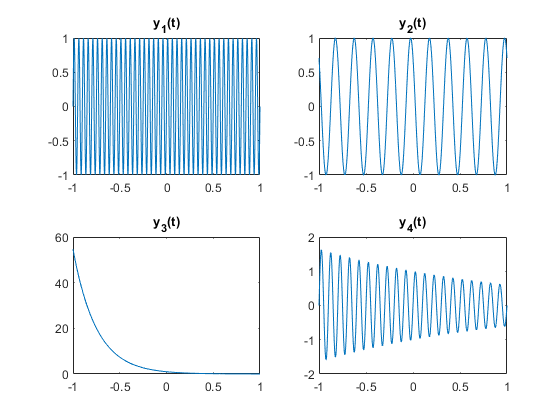

%question 1
t = linspace(-1,1,1000);
y1 = sin(20*pi*alpha*t);
subplot(2,2,1);
plot(t,y1)
title('y_1(t)');

y2= cos(5*pi*alpha*t + (pi/4));
subplot(2,2,2);
plot(t,y2);
title('y_2(t)');

y3 = exp(-2*alpha*t);
subplot(2,2,3);
plot(t,y3);
title('y_3(t)');

y4 = (exp(-0.25*alpha*t)).*(sin(20*pi*t));
subplot(2,2,4);
plot(t,y4);
title('y_4(t)');

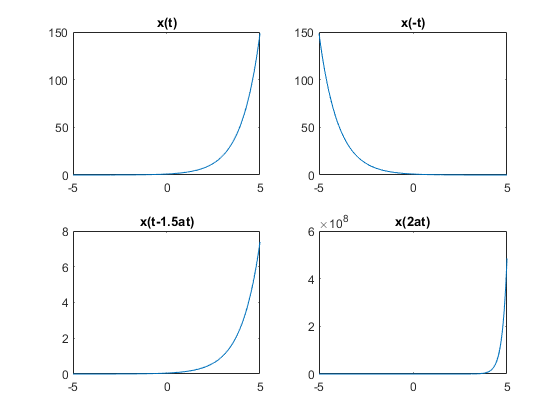

%question 2

t = linspace(-5,5,1000);
subplot(2,2,1);
plot(t,x(t));
title('x(t)')

subplot(2,2,2);
plot(t,x(-t));
title('x(-t)')

subplot(2,2,3);
plot(t,x(t-(1.5*alpha)))
title('x(t-1.5at)')

subplot(2,2,4);
plot(t,x(2*alpha*t))
title('x(2at)')

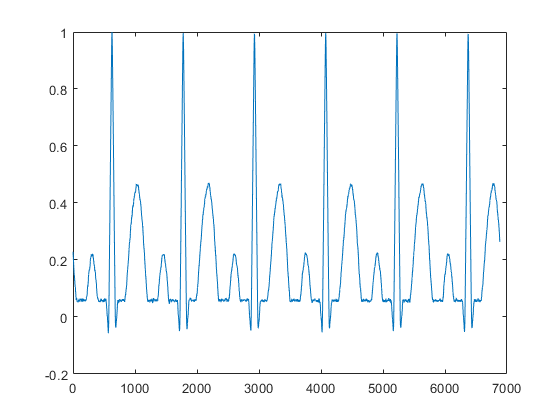


% question 3-1
ECG_Data = importdata('ECG_Data.txt');
subplot(1,1,1);
plot(ECG_Data);

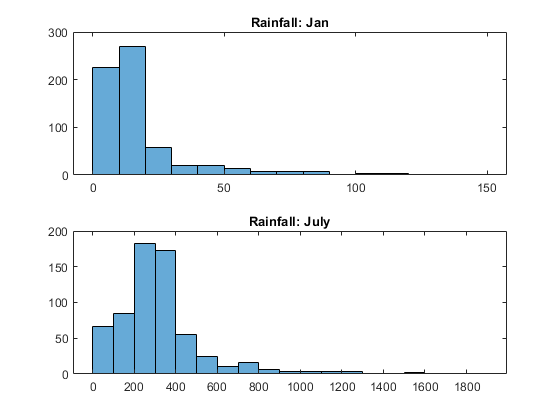

% question 3-2
RainFall_Jan = importdata('RainFallIndia_Jan.txt');
RainFall_July = importdata('RainFallIndia_July.txt');

subplot(2,1,1);
histogram(RainFall_Jan);
title('Rainfall: Jan')

subplot(2,1,2);
histogram(RainFall_July);
title('Rainfall: July')


disp('Mean rainfall - Jan');

Mean rainfall - Jan


mean(RainFall_Jan)

ans = 18.3513

disp('Mean rainfall - July');

Mean rainfall - July


mean(RainFall_July)

ans = 326.0936


disp('standard deviation - Jan');

standard deviation - Jan


std(RainFall_Jan)

ans = 21.0991

disp('standard deviation - July');

standard deviation - July


std(RainFall_July)

ans = 221.5326

% question 3-3
audio_data= importdata('track002.wav');
[y,Fs] = audioread('track002.wav'); 
%reads data from the file named filename, and returns sampled data, y, and a sample rate for that data, Fs.
sound(y,Fs);

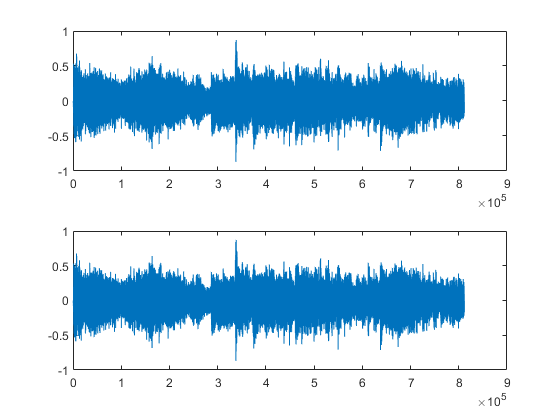

%question 4
[s,Fs] = audioread('Track002.wav');
F =*alpha;
y = s*cos(2*pi*(F/Fs)); 

subplot(2,1,1);
plot(s)
%sound(s,Fs)

subplot(2,1,2);
plot(y)

sound(y,Fs)




%question 5
load handel.mat
t = linspace(1,10,2500);
fun1 = sin(2*pi*200*alpha*t);
fun2 = sin(2*pi*220*alpha*t);
fun3 = [fun1, fun2];
audiowrite('question4.wav',fun3,10000);
[aud_dat,sample_rate] = importdata('question4.wav');
sound(aud_dat,10000);

Error using sound (line 36)
Audio data must be real and floating point.

%question 6 


function y = x(t)
y = exp(t);
end